# DEMO CODE

- Don't forget to add the relevant codes to your MATLAB path

- All simulations are 2D and assume one immobile and one freely diffusing population with the same photophysical parameters (i.e., photoblinking and photobleaching rates). Two-state photoblinking is assumed, while the photobleaching is allowed to occur from either the on- or off-state. The immobile particles are arranged along filaments. Simulated EMCCD noise is present in each simulation, as well.

#### **Simulation info**

**Parameter info**

$D$ is the diffusion coefficient, $k_{\textrm{on}}$ and $k_{\textrm{off}}$ are the photoblinking rates ($k_{\textrm{on}} :\textrm{off}\to \textrm{on}$ rate and $k_{\textrm{on}} :\textrm{on}\to \textrm{off}$ rate), $f_D$ is the fraction of diffusing particles, and $k_p$ is the photobleaching rate, .

**Fast diffusion, slow bleaching**

$D=5\;{\textrm{pixels}}^2 /\textrm{frame}$, $k_{\textrm{on}} =0\ldotp 1\;{\textrm{frame}}^{-1}$, $k_{\textrm{off}} =0\ldotp 9\;{\textrm{frame}}^{-1}$, $f_D =0\ldotp 7\;{\textrm{frame}}^{-1}$, $k_p ={10}^{-4} \;{\textrm{frame}}^{-1}$

The computed ACF from this simulated image series can be fit without considering the effects of time-windowing or photobleaching (see manuscript for more details on the different types of models).

**Slow diffusion, slow bleaching**

$D=0\ldotp 01\;{\textrm{pixels}}^2 /\textrm{frame}$, $k_{\textrm{on}} =1\;{\textrm{frame}}^{-1}$, $k_{\textrm{off}} =0\ldotp 7\;{\textrm{frame}}^{-1}$, $f_D =0\ldotp 65\;{\textrm{frame}}^{-1}$, $k_p ={10}^{-4} \;{\textrm{frame}}^{-1}$

When the diffusion is relatively slow, the time-windowing defined in our fluorescence fluctuations has an effect on the ACF that needs to be accounted for. The effect of the time-windowing is apparent here by the ascending kICS ACF as a function of $|\mathit{\mathbf{k}}|^{2\;}$, therefore we utilize the model that does consider the time-window effect, but not the bleaching effects when fitting this ACF.

% clear variables from workspace and close figures
clear
close all

Choose a simulation to analyze:

sim_choice = 2;

% load in chosen simulated image series under demo/
switch sim_choice
    case 1
        % fast diffusion, slow bleaching
        load('D_5_kon_0.1_koff_0.9_frac_diff_0.7_kp_0.0001.mat')
    otherwise
        % slow diffusion, slow bleaching
        load('D_0.01_kon_1_koff_0.7_frac_diff_0.65_kp_0.0001.mat')
end

Display first simulated image. Since the simulation has periodic boundaries in space, we consider a region of interest (ROI) for analysis.

Choose ROI coordinates (default: $x_1 =y_1 =1$, $x_2 =y_2 =64$):

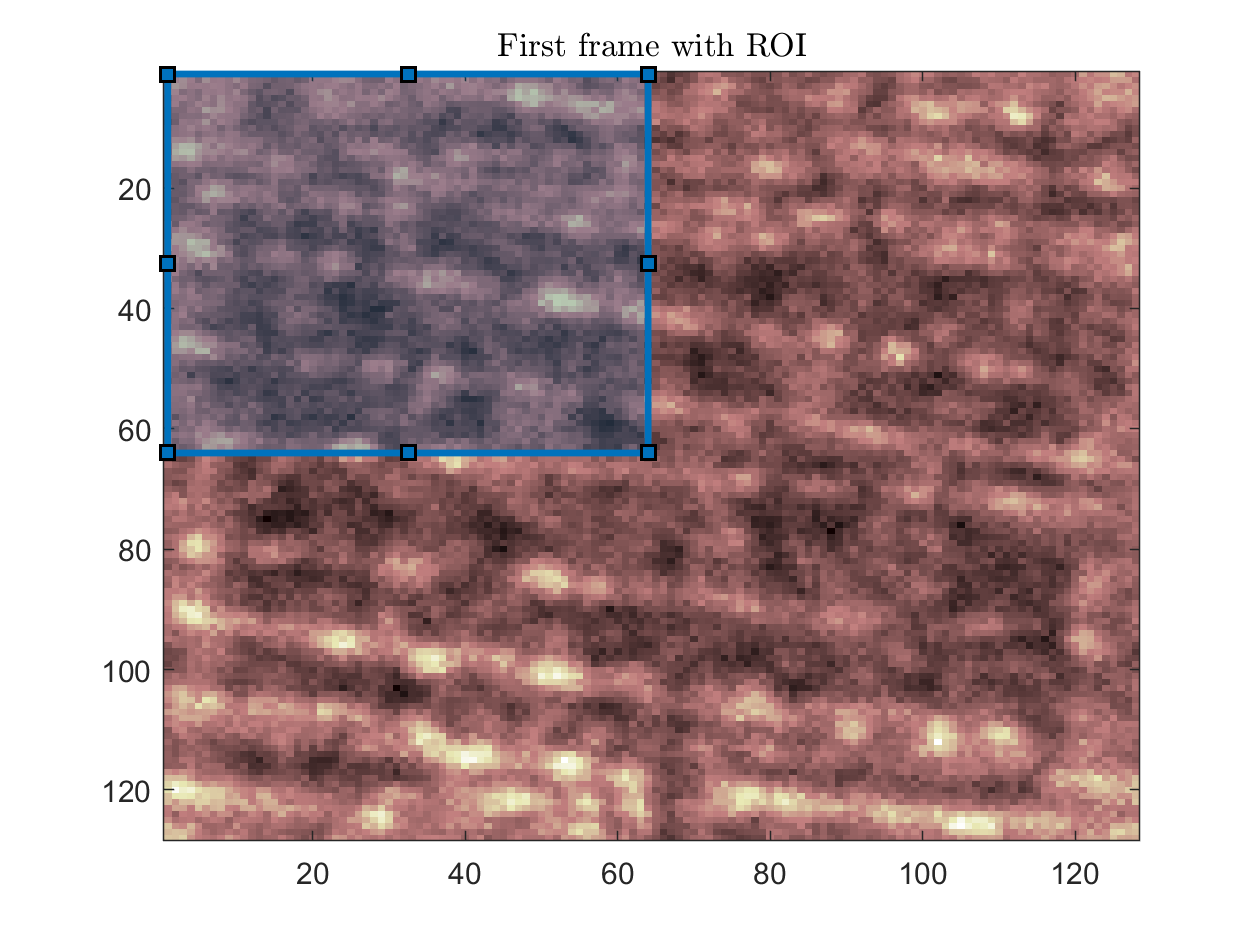

%%% PLOTTING
figure
% view first image in image series
imagesc(J(:,:,1));
colormap(pink)
title('First frame with ROI','Interpreter',"latex")

% select roi for analysis
%
% height of image
h_J = size(J,1);
% width of image
w_J = size(J,2);
%
x1 =1;
x2 =64;
y1 =1;
y2 =64;
% highlight roi within first image
drawrectangle('Position',[x1,y1,abs(x2-x1),abs(y2-y1)]);

#### Fit bleaching intensity trace

(Note: here we fit a single exponential without an offset value because the trace has not sufficiently decayed)

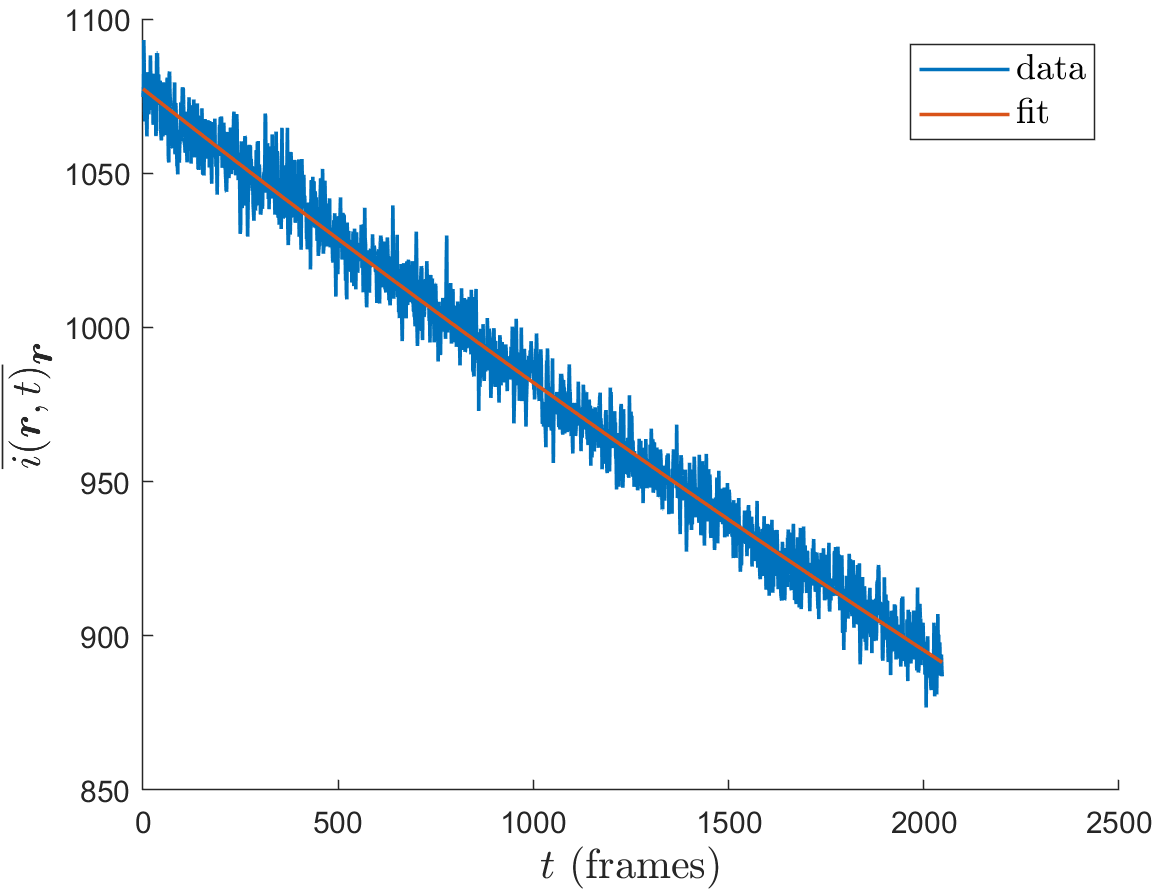

% fit bleaching intensity trace and show results
[p,ci] = bleachFit(J,'fitOffset',0,'showFig',1);

disp(['Fitted bleaching rate: ',num2str(p(2)),' frame^-1.'])

Fitted bleaching rate: 9.255e-05 frame^-1.


disp(['95% confidence interval of bleaching rate: [',num2str(ci(2,1)),',',num2str(ci(2,2)),'] frame^-1.'])

95% confidence interval of bleaching rate: [9.2014e-05,9.3087e-05] frame^-1.


disp('True bleaching rate: 1e-4 frame^-1.')

True bleaching rate: 1e-4 frame^-1.


#### kICS ACF Computation

Choose window size for computing extended kICS autocorrelation (default: $T_w =200\;\textrm{frames}$).

% roi image series
J_roi = J(y1:y2,x1:x2,:);
% get all possible |k|^2 values
kSqVector = getKSqVector(J_roi);
% get bounds of |k|^2
[l,u] = bounds(kSqVector);
% window size
T_w = 200;
% compute kICS autocorrelation function (ACF) without normalization
r_k = kICS(J_roi,'normByLag','none','timeWin',T_w);

Subtract noise from $\tilde{\phi \;} \left(\mathit{\mathbf{k}},\tau =0\right)$ before normalization:

- Compute circularly averaged autocorrelation at $\tau =0$, $\tilde{\phi \;} \left(|\mathit{\mathbf{k}}|^{2\;} ,\tau =0\right)$. This simply averages all points in the autocorrelation with the same $|\mathit{\mathbf{k}}|^{2\;}$ value.

- Average $\tilde{\phi \;} \left(|\mathit{\mathbf{k}}|^{2\;} ,\tau =0\right)$ over an interval of $|\mathit{\mathbf{k}}|^{2\;}$ values where it has sufficiently decayed (depends on the PSF size). This is an estimate of the noise autocorrelation, $\langle \delta_t \tilde{\epsilon} \left(\mathit{\mathbf{k}},t\right)\delta_t {\tilde{\epsilon} }^* \left(\mathit{\mathbf{k}},t+\tau \right)\rangle_t$.

- Subtract this average value from $\tilde{\phi \;} \left(|\mathit{\mathbf{k}}|^{2\;} ,\tau =0\right)$.

. Choose range of $|\mathit{\mathbf{k}}|^{2\;}$ to average for noise estimation (default: $10\le |\mathit{\mathbf{k}}|^{2\;} \le 15\;{\textrm{pixels}}^{-2}$):

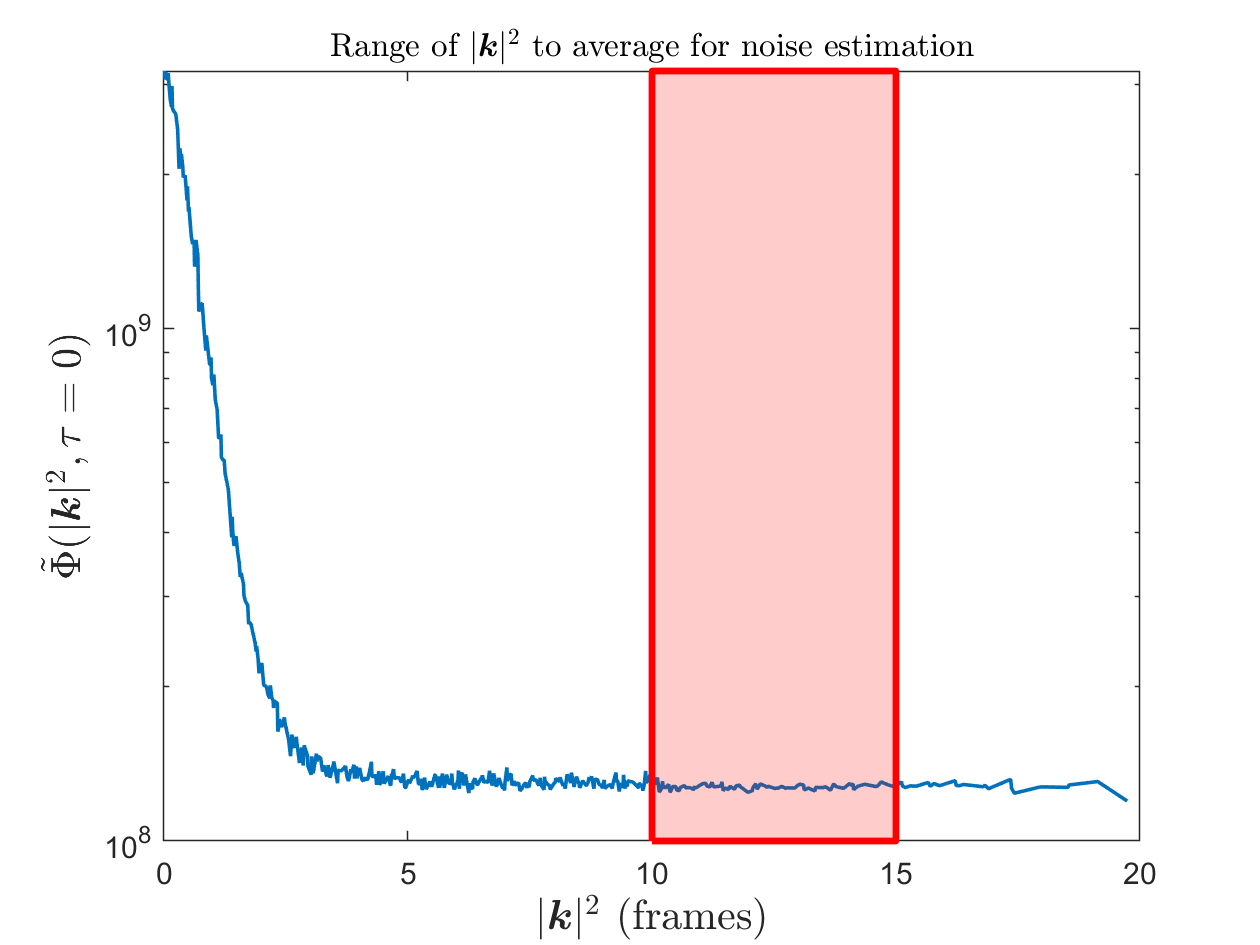

% circularly averaged autocorrelation in k-squared
r_k_circ = circular(r_k);
% circularly averaged autocorrelation in k-squared at tau = 0
r_k_0_circ = r_k_circ(:,1);
%

%%% PLOTTING
figure
% plot kICS autocorrelation at tau=0
semilogy(kSqVector,r_k_0_circ(2:end),'LineWidth',1.2)
% label plot
title('Range of $|\mbox{\boldmath$k$}|^2$ to average for noise estimation','interpreter','latex')
xlabel('$|\mbox{\boldmath$k$}|^2$ (frames)','interpreter','latex','fontsize',14)
ylabel('$\tilde{\Phi}(|${\boldmath$k$}$|^2,\tau=0)$','interpreter','latex','fontsize',14)
% k-squared values to average and subtract from autocorrelation at tau=0
% ksq_min_noise <= |k|^2 <= ksq_max_noise
ksq_min_noise =10;
ksq_max_noise = 15;
% highlight possible range of |k|^2 to average for noise estimation
yl = ylim;
drawrectangle("Position",[ksq_min_noise,yl(1),ksq_max_noise-ksq_min_noise,yl(2)-yl(1)],"Color",'r',"InteractionsAllowed","none");

% noise subtracted kICS autocorrelation at tau=0
r_k_0_sub = kICSSubNoise(r_k,ksq_min_noise,ksq_max_noise);
% noise subtracted circularly averaged autocorrelation at tau=0
r_k_0_circ_sub = circular(r_k_0_sub(:,:,1));

#### Plot (extended) kICS ACF curves

The fit of the ACF, $\tilde{\Phi \;} \left(\mathit{\mathbf{k}},\tau \right)$, is done over a chosen range of $\tau$ and $|\mathit{\mathbf{k}}|^2$. Here are some reasons why the fit is not performed over the entire range:

- At high $|\mathit{\mathbf{k}}|^2$, our defined normalization in the ACF leads to division by zero. This is because $\tilde{\phi \;} \left(\mathit{\mathbf{k}},\tau =0\right)$ decays to zero, if the noise is properly subtracted. The decay of the $\tau =0$ curve is dependent on the PSF size.

- The autocorrelation curves as a function of $|\mathit{\mathbf{k}}|^2$ become noisier at higher $\tau$ values.

- Image series with faster bleaching rates yield kICS autocorrelations with artifacts at low values of $|\mathit{\mathbf{k}}|^2$. This can be mitigated by choosing smaller time windows, $T_w$, however.

Choose range of $\tau$ and $|\mathit{\mathbf{k}}|^2$ to plot and fit (default: $\tau =1\to 10\;\textrm{frames}$, $\textrm{eps}\le |\mathit{\mathbf{k}}|^2 \le 1\ldotp 8\;{\textrm{pixels}}^{-2}$):

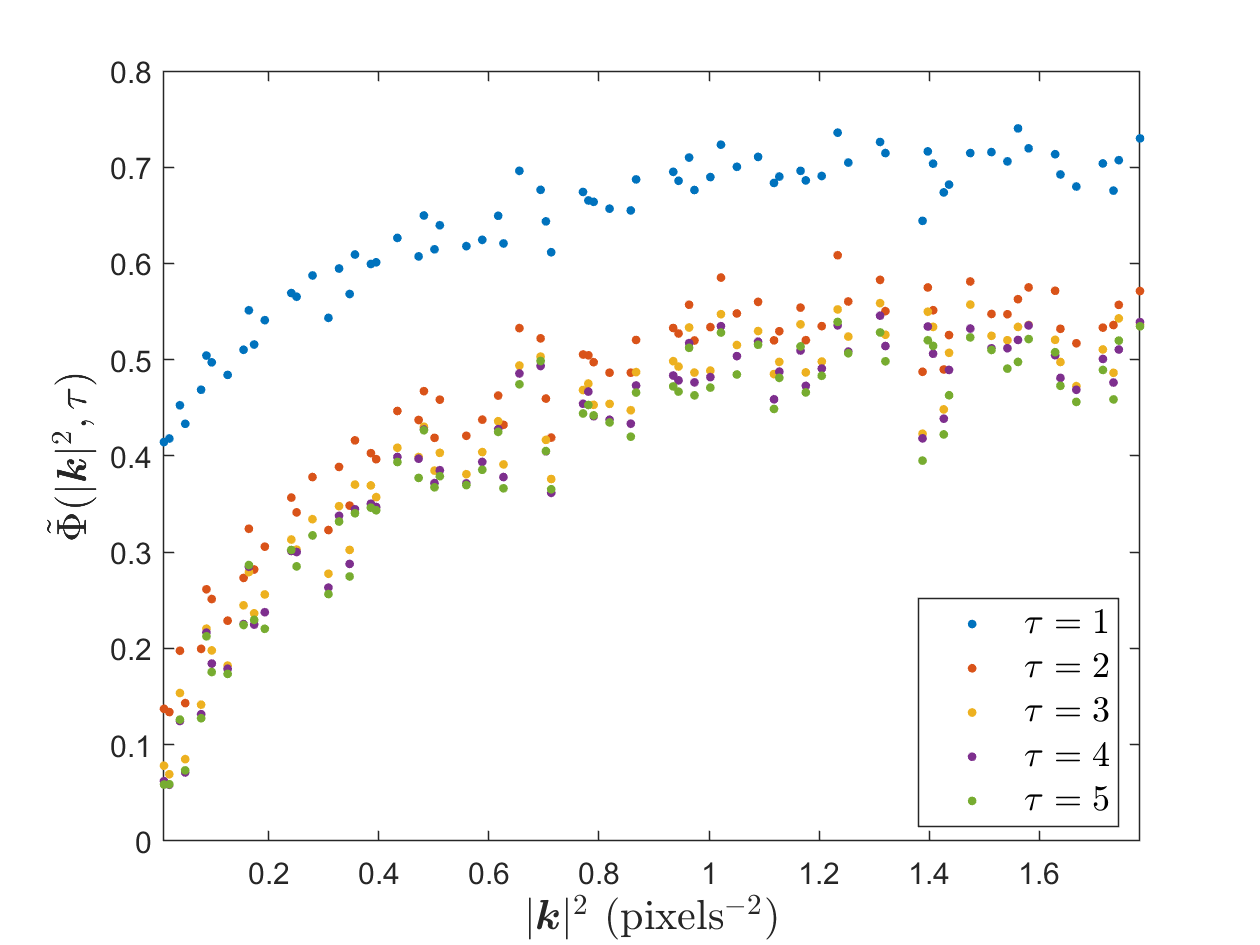

% pick a range of tau lags to fit
tauVector = 1:10;
% pick a range of k-squared to plot and fit
kSqMin = eps;
kSqMax = 1.8;
[kSqVectorSubset,kSqSubsetInd] = getKSqVector(J_roi,'kSqMin',kSqMin,'kSqMax',kSqMax);
% restrict autocorrelation to be between [kSqMin,kSqMax]
r_k_circ_cut = r_k_circ(kSqSubsetInd,tauVector+1);

% do same for denominator of ACF
r_k_0_circ_cut = r_k_0_circ_sub(kSqSubsetInd,1);

% normalization
r_k_norm = real(r_k_circ_cut./r_k_0_circ_cut);

%%% PLOTTING
figure()
hold on
box on
% k-squared for plotting theory and fit curves
ksq2plot = linspace(kSqVectorSubset(1),kSqVectorSubset(end),1e3);
% choose time lags to plot
plotTauLags = 1:5;
% get indices in tauVector corresponding to plotTauLags values
[~,plot_idx] = ismember(plotTauLags,tauVector);
% pre-assign colormap according to length(plotTauLags)
color = lines(length(plotTauLags));
% pre-allocate cell for legend
plotLegend = cell(1,length(plotTauLags));
% pre-allocate array for chart line objects
h_sim_data = zeros(1,length(plotTauLags));
% loop and plot ACF as a function of k-squared over fixed time lag
for tauInd = 1:length(plotTauLags)
    h_sim_data(tauInd) = plot(kSqVectorSubset,r_k_norm(:,plot_idx(tauInd)),...
        '.','markersize',10,'Color',color(tauInd,:)); % plot simulated kICS ACF
    plotLegend{tauInd} = ['$\tau = ' num2str(plotTauLags(tauInd)) '$'];
end
% plot labeling
xlabel('$|${\boldmath$k$}$|^2$ (pixels$^{-2}$)','interpreter','latex','fontsize',14)
ylabel('$\tilde{\Phi}(|${\boldmath$k$}$|^2,\tau)$','interpreter','latex','fontsize',14)
legend(h_sim_data,plotLegend,'fontsize',12,'interpreter','latex','Location','best')
% set x-axis limits to match chosen k-squared range
xlim([kSqVectorSubset(1) kSqVectorSubset(end)])

#### Comparing the kICS ACF curves with theory

The 2D theory functions take input $\left\lbrack D,\rho_{\textrm{on}} ,K,f_D \right\rbrack$, where $D$ is the diffusion coefficient, $\rho_{\textrm{on}}$ is the fraction of time spent in the fluorescent on-state, $K\equiv k_{\textrm{on}} +k_{\textrm{off}}$ is the sum of the photoblinking rates ($k_{\textrm{on}} :\textrm{off}\to \textrm{on}$ rate and $k_{\textrm{on}} :\textrm{on}\to \textrm{off}$ rate), and $f_D$ is the fraction of diffusing particles. Here we use the model that does **not** consider the time-window or bleaching effects on the autocorrelation (see manuscript for more details on the different types of models).

disp(['true simulated parameters: ',mat2str(true_params)])

true simulated parameters: [0.01 0.588235294117647 1.7 0.649982166210914]


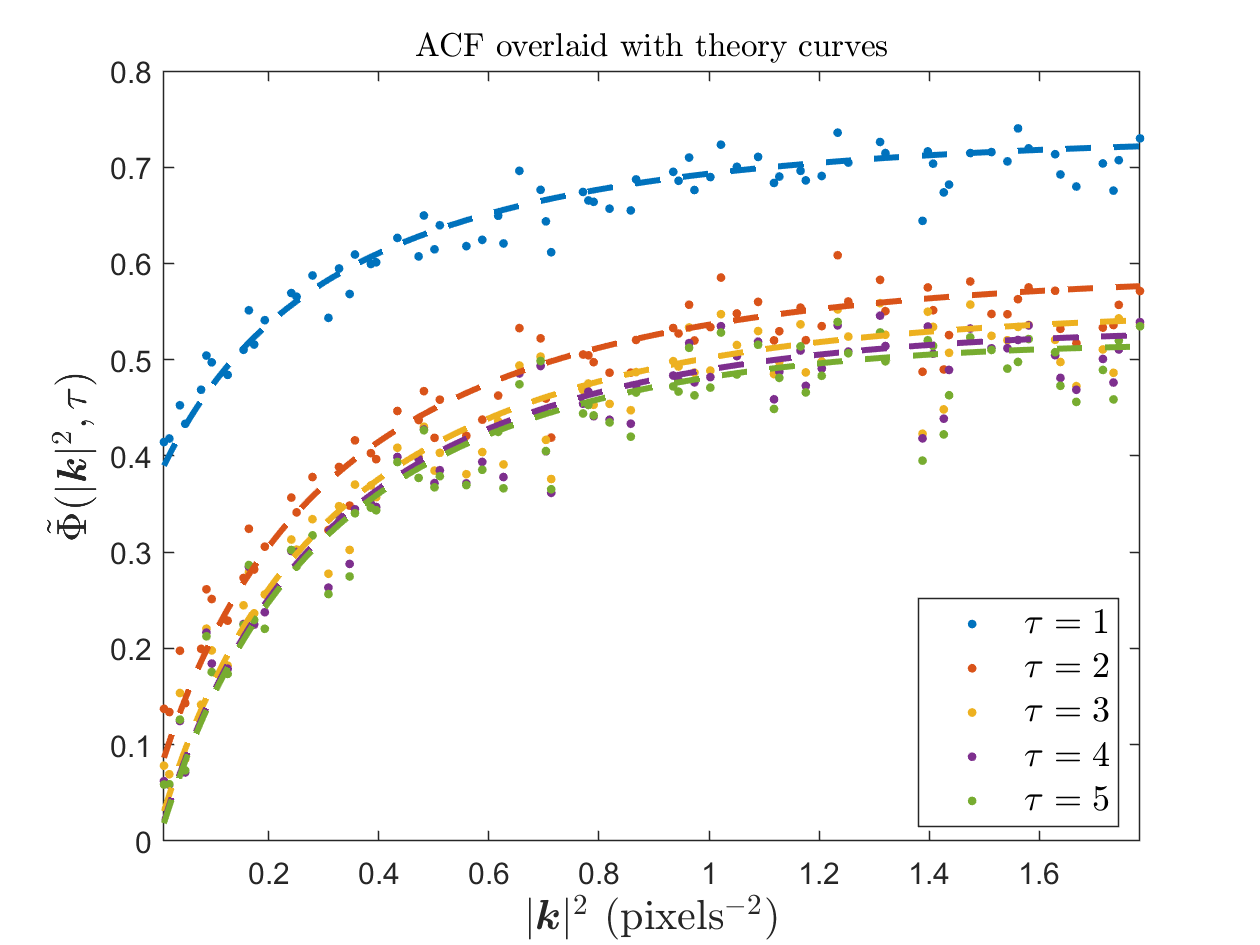

% function handle for ACF model
switch sim_choice
    case 1
        % time-window and bleaching effects not considered
        fit_fun = @(params,ksq,tau) timeIntkICSFit(params,ksq,tau);
    otherwise
        % time-window effect considered, bleaching effect not considered
        fit_fun = @(params,ksq,tau) kICSSlideWinFit(params,ksq,tau,T_w);
end

%%% PLOTTING
figure
ax_theory = gca;
hold on
box on
% replot previous figure
for i = 1:length(h_sim_data)
    copyobj(h_sim_data(i),ax_theory)
end
% pre-allocate array for chart line objects
h_theory = zeros(1,length(plotTauLags));
% loop and plot theory ACF curves as a function of k-squared over fixed time lag
for tauInd = 1:length(plotTauLags)
    h_theory(tauInd) = plot(ksq2plot,fit_fun(true_params,...
        ksq2plot,plotTauLags(tauInd)),...
        '--','Color',color(tauInd,:),'LineWidth',2);
end
% plot labeling
title('ACF overlaid with theory curves','interpreter','latex')
xlabel('$|${\boldmath$k$}$|^2$ (pixels$^{-2}$)','interpreter','latex','fontsize',14)
ylabel('$\tilde{\Phi}(|${\boldmath$k$}$|^2,\tau)$','interpreter','latex','fontsize',14)
legend(plotLegend,'fontsize',12,'interpreter','latex','Location','best')
% set x-axis limits to match chosen k-squared range
xlim([kSqVectorSubset(1) kSqVectorSubset(end)])

#### Fitting kICS ACF curves

We simultaneously fit the curves for all parameters using a global search and fmincon as the local solver (this minimizes a function, sum of squared residuals in our case, with constraints). Recall we have $\rho_{\textrm{on}} \le 1$ and $f_D \le 1$ as constraints.

% format of parameter vector [D,rho_on,K,f_D]
%
% fix random number generator for reproducibility
% if this isn't done, repeat fit with new initial parameter guesses until model agrees with data
rng(12)
% initial guess of parameters
params_guess = [rand rand rand rand];
% lower bounds on parameters
lb = eps*ones(1,4);
% upper bounds on parameters
ub = [Inf 1 Inf 1];
%

% fit ACF
%
% define objective function for local solver
switch sim_choice
    case 1
        % time-window and bleaching effects not considered
        err = @(params) timeIntkICSFit(params,kSqVectorSubset,tauVector,...
            'err',r_k_norm);
    otherwise
        % time-window effect considered, bleaching effect not considered
        err = @(params) kICSSlideWinFit(params,kSqVectorSubset,tauVector,T_w,...
            'err',r_k_norm);
end
% options for local solver
opts = optimoptions(@fmincon,'Algorithm','interior-point');
% define local problem
problem = createOptimProblem('fmincon','objective',...
    err,'x0',params_guess,'lb',lb,'ub',ub,'options',opts);
% create global search object
gs = GlobalSearch('Display',"off");
% perform fit
opt_params = run(gs,problem);
% display fit results
disp(['optiimal parameters: ',mat2str(opt_params)])

optiimal parameters: [0.0112172051329631 0.599675017355127 1.67897537343587 0.573564099323989]


disp(['true simulated parameters: ',mat2str(true_params)])

true simulated parameters: [0.01 0.588235294117647 1.7 0.649982166210914]


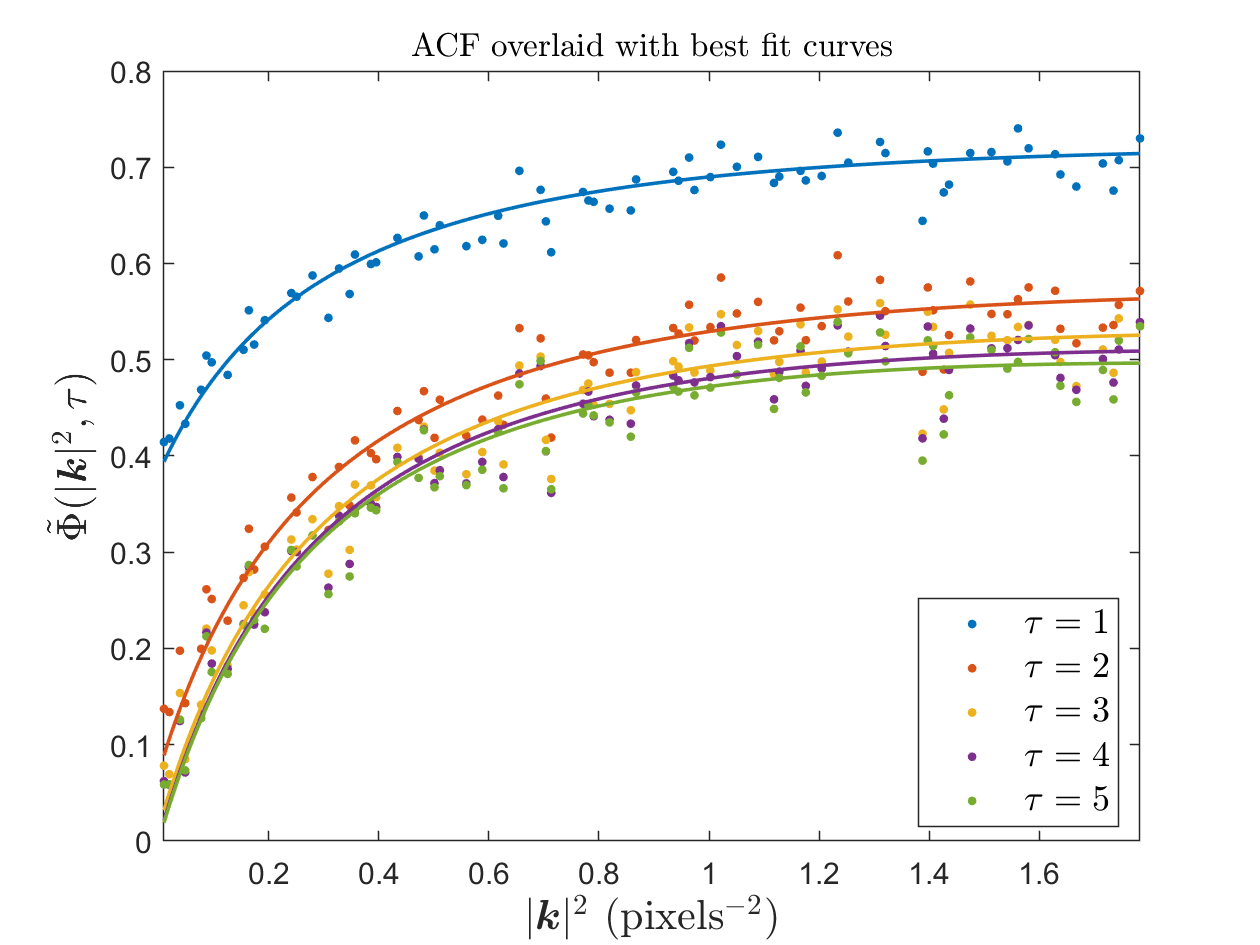

%

%%% PLOTTING
figure
ax_fit = gca;
hold on
box on
% replot previous figure
for i = 1:length(h_sim_data)
    copyobj(h_sim_data(i),ax_fit)
end
% plot best fit of kICS ACF
for tauInd = 1:length(plotTauLags)
    plot(ksq2plot,fit_fun(opt_params,ksq2plot,plotTauLags(tauInd)),...
        'Color',color(tauInd,:),'LineWidth',1.2)
end
% plot labeling
title('ACF overlaid with best fit curves','interpreter','latex')
xlabel('$|${\boldmath$k$}$|^2$ (pixels$^{-2}$)','interpreter','latex','fontsize',14)
ylabel('$\tilde{\Phi}(|${\boldmath$k$}$|^2,\tau)$','interpreter','latex','fontsize',14)
legend(plotLegend,'fontsize',12,'interpreter','latex','Location','best')
% set x-axis limits to match chosen k-squared range
xlim([kSqVectorSubset(1) kSqVectorSubset(end)])